# Import "data_10MPa_118s_Oil_20_deg_Spontanversagen"

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\data");
addpath(fpath,dpath)

beta_range = 90:7.5:270;
sensor_position = 97.5:7.5:270;

### Import & 基本处理

%注意！这张表格没有meta，要单独处理！
%未来改进：在程序中增加识别是否存在meta的部分

%default: TableDescription = FileName 之后再改
FileName_in_String = "data_10MPa_118s_Oil_20_deg_Spontanversagen";
TableDescription = FileName_in_String;

%read Table
Spontanversagen_10MPa_20deg = readtable(FileName_in_String+".xlsx","TextType","string");

Spontanversagen_10MPa_20deg.Properties.Description = TableDescription;

%删除meta
%Spontanversagen_10MPa_20_deg = removevars(Spontanversagen_10MPa_20_deg,["meta0" "meta1" "meta2"]);

%统一表格变量的名称，以便于代码复用 rename -> timeStamp, spez_Pressung, Gleitgeschwindigkeit
Spontanversagen_10MPa_20deg = renamevars(Spontanversagen_10MPa_20deg,{'timeStamp' 'spez_Pressung' 'Gleitgeschwindigkeit_m_s_'} ...
    ,{'timeStamp', 'spez_Pressung', 'Gleitgeschwindigkeit'});

### Visualization

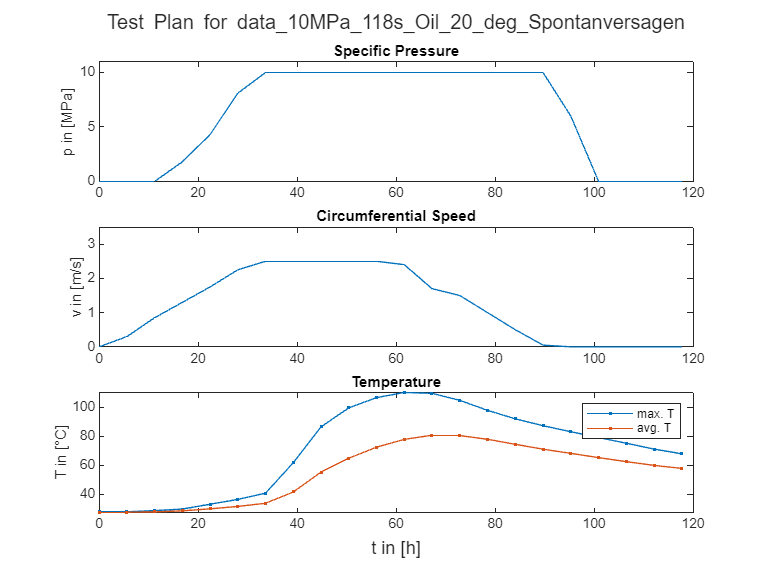

The documented max. T reached 110 ℃.


testplan_visualization(Spontanversagen_10MPa_20deg); 

Animation for data_10MPa_118s_Oil_20_deg_Spontanversagen: 


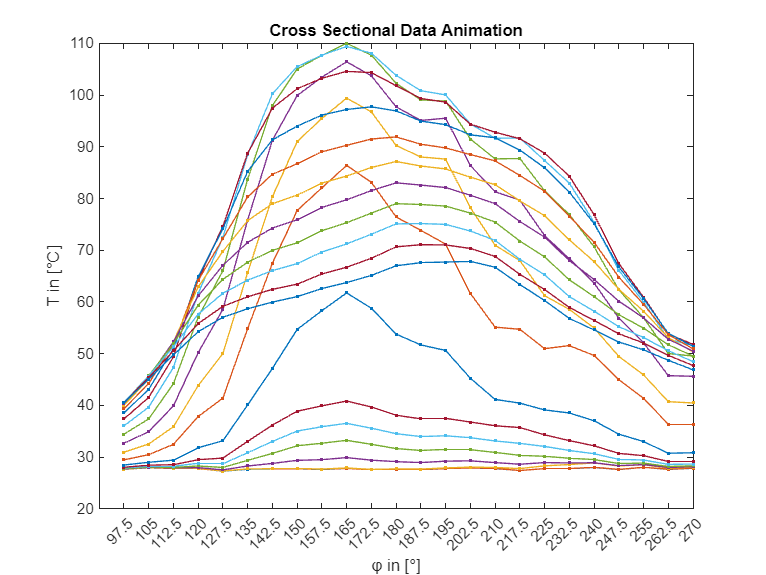


% 时间截面动画
timeCrossSection_animation(sensor_position,Spontanversagen_10MPa_20deg,1);

T_max position of data_10MPa_118s_Oil_20_deg_Spontanversagen: 


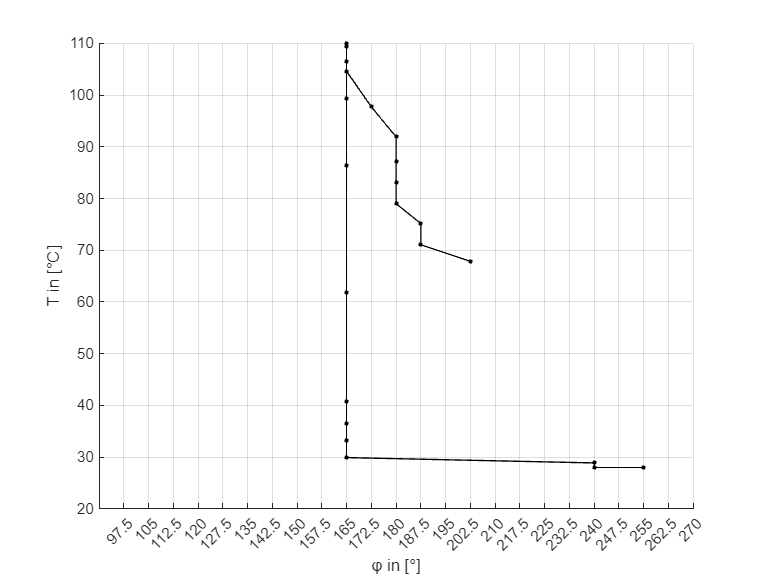

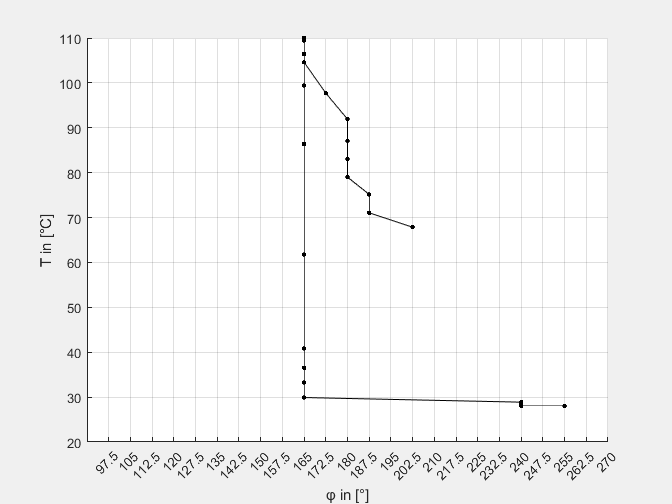

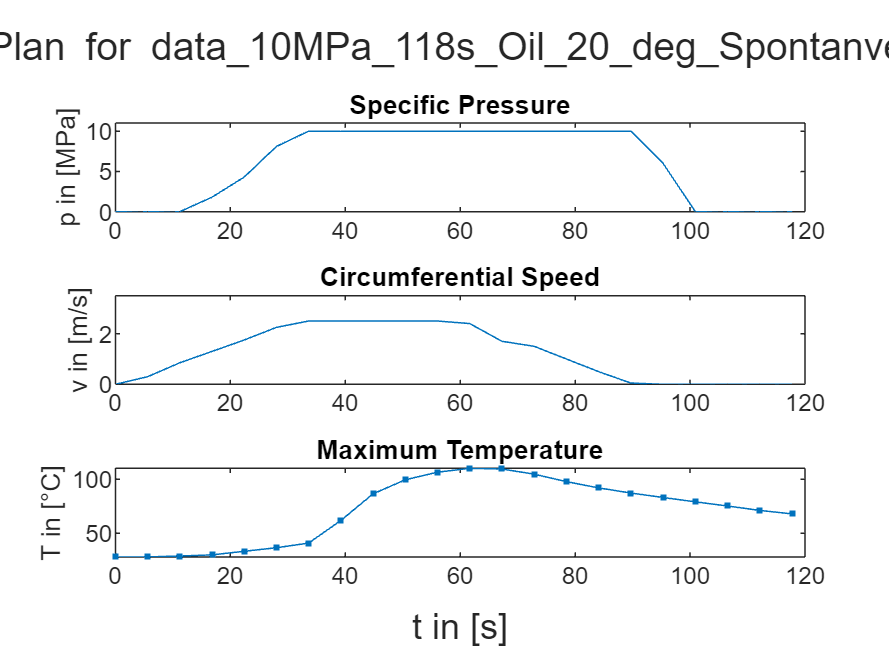

The documented max. T reached 110 ℃.


Animation for data_10MPa_118s_Oil_20_deg_Spontanversagen: 


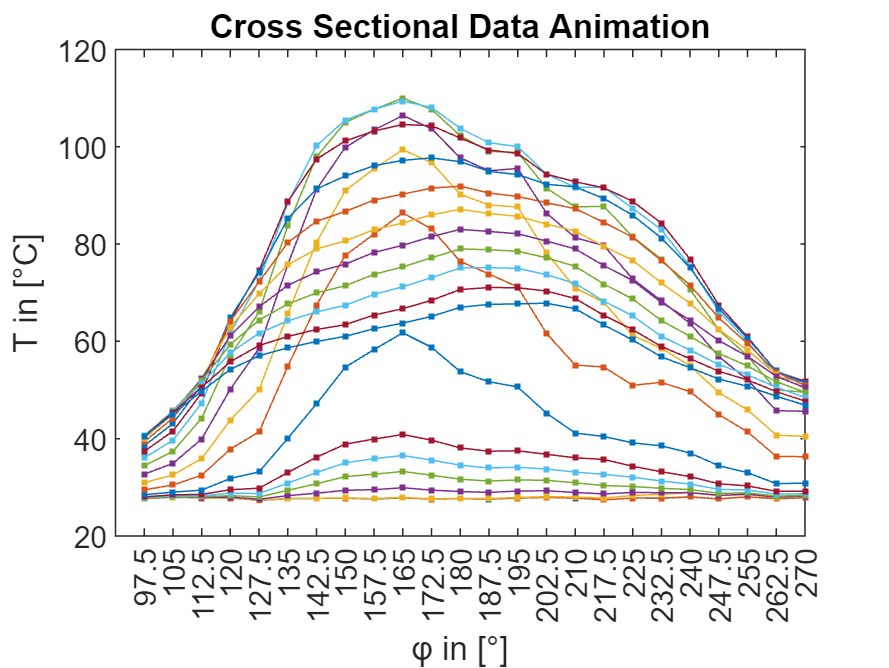

T_max position of data_10MPa_118s_Oil_20_deg_Spontanversagen: 


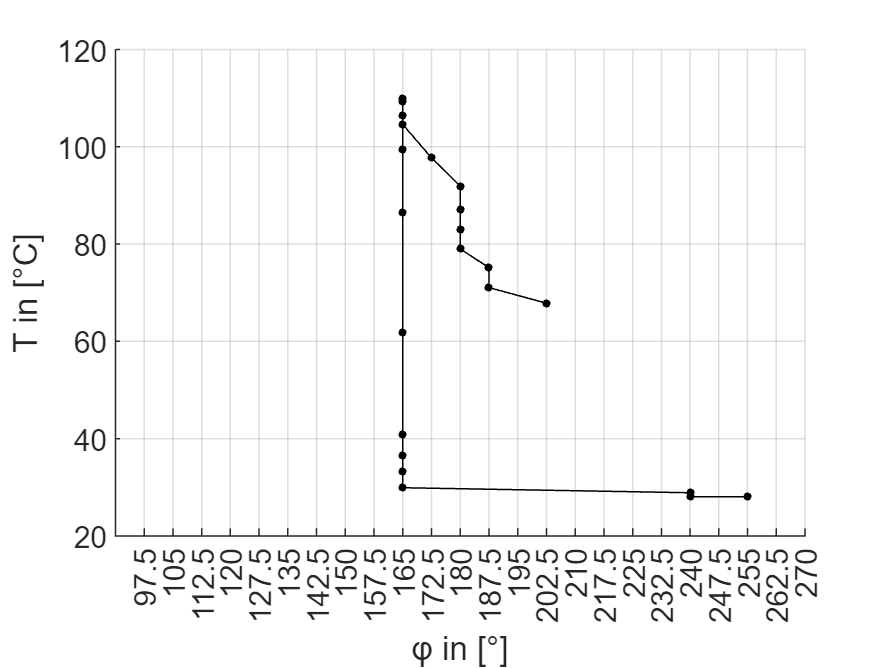


% 最大值位置动画
maxT_position_animation(sensor_position,Spontanversagen_10MPa_20deg);